% Test the 3D LIDAR equations
l = 2; % set the arm
phi = 0; % set the vertical angle
r = linspace(1,1,100); % fake scan data with r = 1 at every angle theta
theta = linspace(0,270/180*pi,100); % fake scan data with r = 1 at every angle theta
%plot3(x,z,y,'*') % plot points in 3d (z is out of the page)
xlabel('x')
ylabel('y')
zlabel('z')
angs = theta - (135*pi/180);
hold on;
axis equal
for phi = deg2rad(-20:10:45)
    z = l.*sin(phi)+r.*cos(phi).*cos(angs); % x coordinate from base
    x = l.*cos(phi)-r.*sin(phi).*cos(angs); % y coordinate from base
    y = r.*sin(angs); % z coordinate from base
    plot3(x,y,z,'*') 
    quiver3(0,0,0,l*cos(phi),0,l*sin(phi),'off')
end 

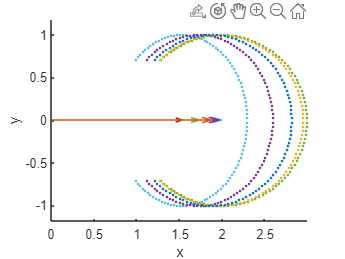

clf
r = linspace(1,1,100);
l = 2;
phi = 1;
lidar_step = linspace(0,270/180*pi,100); % 0-270 degrees in radians
angs = lidar_step - (135*pi/180); % subtracted 135 degrees in radians to make center of scan 0: range is -135 to 135 degrees in radians
[x_lidar_scan,y_lidar_scan] = pol2cart(angs,r); % converting polar coordinates to cartesian to make vector math easier
x_to_base = x_lidar_scan + l; % x direction distance from point to base 
base_frame_vecs = [x_to_base;y_lidar_scan;zeros(1,length(x_to_base))];
rotation_matrix_y = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];
robot_frame_vecs = rotation_matrix_y * base_frame_vecs;
hold on 
for phi = deg2rad(-20:10:45)
    lidar_step = linspace(0,270/180*pi,100); % 0-270 degrees in radians
    angs = lidar_step - (135*pi/180); % subtracted 135 degrees in radians to make center of scan 0: range is -135 to 135 degrees in radians
    [x_lidar_scan,y_lidar_scan] = pol2cart(angs,r); % converting polar coordinates to cartesian to make vector math easier
    x_to_base = x_lidar_scan + l; % x direction distance from point to base 
    base_frame_vecs = [x_to_base;y_lidar_scan;zeros(1,length(x_to_base))];
    rotation_matrix_y = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];
    robot_frame_vecs = rotation_matrix_y * base_frame_vecs;
    plot3(robot_frame_vecs(1,:),robot_frame_vecs(2,:),robot_frame_vecs(3,:),'.');
    quiver3(0,0,0,l*cos(-phi),0,l*sin(-phi),'off')
end 
axis equal
xlabel('x')
ylabel('y')
zlabel('z')